% Section 1
n_in = 256;
nv=0:(n_in-1);

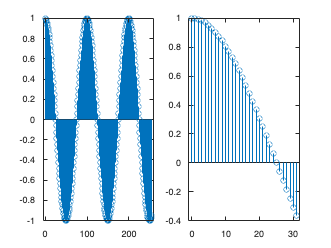

% Section 2

% Part 3
% x = [1, zeros(1,(n_in-1))];

% Part 4
% x = square((2*pi/256)*nv);

% Part 5
freq = 0.01;
x = cos(2*pi*freq*nv);

subplot(1,2,1)
stem(nv,x)

subplot(1,2,2)
stem(nv(1:32),x(1:32))

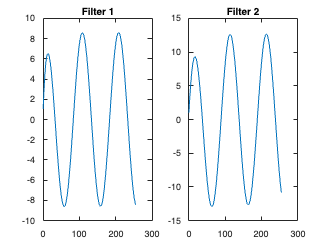

% Section 3

% Filter 1
a1 = [1, -.9];
b1 = 1;
y1 = filter(b1, a1, x);

% Filter 2
a2 = [1, -.95];
b2 = 1;
y2 = filter(b2, a2, x);

subplot(1,2,1)
plot(nv,y1)
title("Filter 1")


subplot(1,2,2)
plot(nv,y2)
title("Filter 2")


min_val_y1 = min(abs(y1))

min_val_y1 = 0.0362

min_val_y2 = min(abs(y2))

min_val_y2 = 0.1815

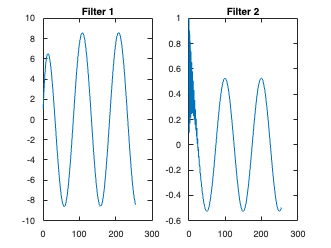

% Section 4

% Filter 1
a1 = [1, -.9];
b1 = 1;
y1 = filter(b1, a1, x);

% Filter 2
a2 = [1, 0.9];
b2 = 1;
y2 = filter(b2, a2, x);

subplot(1,2,1)
plot(nv,y1)
title("Filter 1")


subplot(1,2,2)
plot(nv,y2)
title("Filter 2")


min_val_y1 = min(abs(y1))

min_val_y1 = 0.0362

min_val_y2 = min(abs(y2))

min_val_y2 = 0.0084

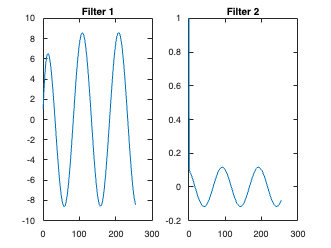

% Section 5

% Filter 1
a1 = [1, -.9];
b1 = 1;
y1 = filter(b1, a1, x);

% Filter 2
a2 = b1;
b2 = a1;
y2 = filter(b2, a2, x);

subplot(1,2,1)
plot(nv,y1)
title("Filter 1")


subplot(1,2,2)
plot(nv,y2)
title("Filter 2")


min_val_y1 = min(abs(y1))

min_val_y1 = 0.0362

min_val_y2 = min(abs(y2))

min_val_y2 = 4.9044e-04